# TTT4135 MULTIMEDIA SIGNAL PROCESSING Assignment 1

close all;
clear;

## Part 1:

### 1: Still image compression:

#### a)

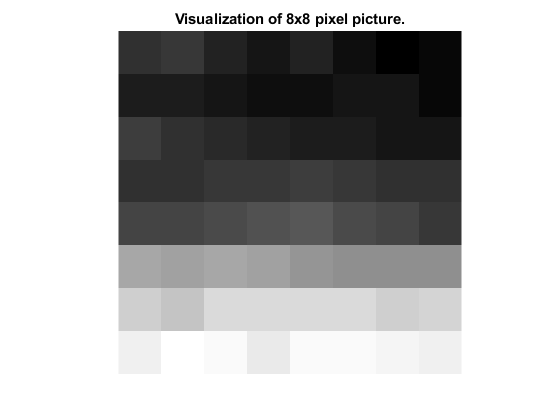

pic_mat =  [124 125 122 120 122 119 117 118
            121 121 120 119 119 120 120 118
            126 124 123 122 121 121 120 120
            124 124 125 125 126 125 124 124
            127 127 128 129 130 128 127 125
            143 142 143 142 140 139 139 139
            150 148 152 152 152 152 150 151
            156 159 158 155 158 158 157 156];

figure()
imshow(log(abs(pic_mat)),[],'InitialMagnification','fit');
title('Visualization of 8x8 pixel picture.')

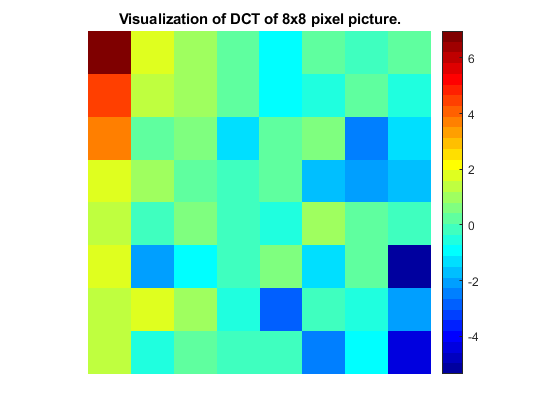

dct_mat = dct2(pic_mat);

figure()
imshow(log(abs(dct_mat)),[],'InitialMagnification','fit');
title('Visualization of DCT of 8x8 pixel picture.')
colormap(gca,jet(32))
colorbar

Here we see that the highest consentration of frequencies in the picutre is in the low frequencies. Elsewhere we have some minor contributions to some of the higher frequency components.

#### b)

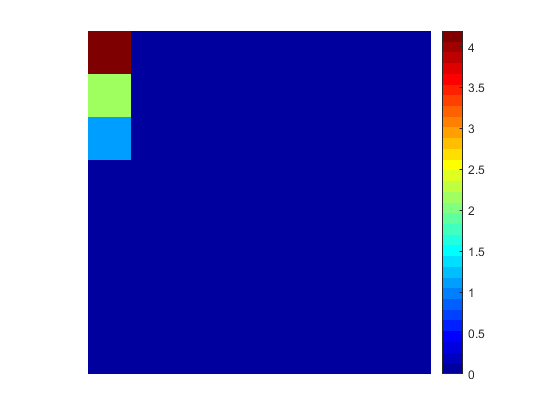

quant_table =  [16 11 10 16  24  40  51  61;
                12 12 14 19  26  58  60  55;
                14 13 16 24  40  57  69  56;
                14 17 22 29  51  87  80  62;
                18 22 37 56  68 109 103  77;
                24 35 55 64  81 104 113  92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103  99];

k = floor((dct_mat./quant_table) + 0.5);

figure()
imshow(log(abs(k)),[],'InitialMagnification','fit');
colormap(gca,jet(32))
colorbar

After doing the quantization most of the semi-high and high frequency components have been zeroed out, while the low frequencies are kept.

By encoding/quantizing the image after having done the dct we are able to filter out most of the irrelevant information in the picture. While if we had quantized the picture first, then done the dct it would first have filtered the image by the quantization table, then piced out the low-high frequencie components of the distorted quantized version of the origianl image. Which would not help in reducing the size of the image by removing irrelevancy, it would just make another distorted version if the original image.

#### c)

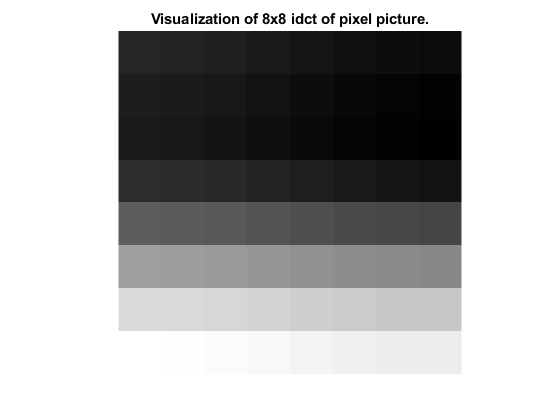

% TODO: ask in help lecture if this is sufficient, or if we have to use
% another formula (same with calculation of PSNR).
dct_mat_inv = round((k).*quant_table);
idct_pic = idct2(dct_mat_inv);

figure()
imshow(log(abs(idct_pic)),[],'InitialMagnification','fit');
title('Visualization of 8x8 idct of pixel picture.')

Based on the following formulas:

$\text{PSNR}_{dB} = 10\cdot \text{log}_{10} \frac{255^2}{\sigma_e^2}$, where $\sigma_e^2 = \frac{1}{MN}\sum_{m=1}^M \sum_{n=1}^N|u(m,n)- \hat u (m,n)|^2$ (from lecture 2, slide 47)

We get the following PSNR:

PSNR = calc_PSNR(pic_mat,idct_pic);
fprintf('PSNR = %f dB\n', PSNR);

PSNR = 40.628971 dB


### 2 - Prediction:

#### a)

Given $x(n)
$, with auto-correlation given by $R_x(k) $, with $R_x(0) = \sigma_x, \text{ } R_x(1) = a, \text{ } R_x(k)=0, \text{ for}  \text{ } |k|>1.$

Starting with the Normal Equation we have:


$$\sum_{k=0}^p a_k \gamma_{xx}[n-e] = - \gamma_{xx}[n]
$$


Using p = 2 for second order LP we get:


$$(1) \text{ } a_1 \gamma_{xx}[0] + a_2 \gamma_{xx}[-1] = -\gamma_{xx}[1]$$



$$(2) \text{ } a_1 \gamma_{xx}[1] + a_2 \gamma_{xx}[0] = - \gamma_{xx}[2]$$


From what was given above, and having that $R_x(k) == \gamma_{xx}[k]$, we have:


$$\gamma_{xx}[0] = \sigma_x, \text{ } \gamma_{xx}[1] = \gamma_{xx}[-1] = a \text{ and otherwise } \gamma_{xx}[k] = 0$$
 

Putting these values into the above equations (1) and (2) we get the equation set


$$(1) \text{ } a_1\sigma_x + a_2\cdot a = -a$$



$$(2) \text{ } a_1\cdot a + a_2\sigma_x = 0$$



$$\left[\matrix{ \sigma_x & a \cr a & \sigma_x}\right] = \left[\matrix{ -a\cr0}\right]$$
 
$$\rightarrow
\left[\matrix{ 1 & 0 \cr 0 & 1 }\right] = \left[\matrix{- \frac{a\sigma_x}{\sigma_x^2 - a^2} \cr \frac{a^2}{a^2 - \sigma_x^2}}\right]$$


Hence the coefficients for the optimal linear predictior is:


$$\text{ } a_1 = -\frac{a\sigma_x}{\sigma_x^2 - a^2} \text{ and } a_2 = \frac{a^2}{a^2 - \sigma_x^2}$$


### 3 - Compression Basics:

#### a)

Lossless compression consists of two main steps. The first is using a wavelet or dct transform for redundancy reduction, and the last one is coding the "image" with a lossless coding shceme.

For lossy compression we first have a similar step to the lossless compression, where redundancy is handeled by a wavelet or dct transform, then following that the image is quantized to remove irrelevancy (this is mainly where the loss is introduced) and lastly the image file is coded with a fitting coding scheme.

#### b)

Partly answered in a) 

The process of quantization starts by defining a finite set of allowed values. For a grayscaled picture this would normally be a limitation in the number of bits used to represent each pixel value. Each pixel will there after get a new value as closely corresponding to the original value as possible. Due to the nature of this method, it will no longer be possible to re-transform the image into its original form without errors.

Using DCT or wavelet transform redundancy between neighboring pixels are reduced, while still keeping the key features like edges.

Using wavelet transform produces coefficients equal in number to the amout of pixels in the image. Doing this allows us to concentrate the information in a few coefficients, the ones corresponding to the low frequencies. In doing this, the image can be more easily compressed.

Using DCT produces "blocks" of a set number of pixels for compression. The results of this are that blocky compression artifacts can appear if the DCT compression is too heavy.

#### c)

In most modern applications, DWT is the prefered method as it provides the better compression ration without loss of data. DCT still sees a lot of use however due to it's low processing requirements.

The most common algorithm for DWT is Daubechies wavelets. Type-II DCT is the most common DCT algorithm.

Rate–distortion optimized quantization is the most common quantization algorithm used for lossy compression.

For lossless compression scheme there is a variaty of methods that see widespread use. Some of theses include RLE, Huffman coding, and Arithmetic coding. Specifically for graphics PDF, PNG and JPEG 2000 are some of the more widespread methods.

DCT is the most commonly used method for lossy compression.

#### d)

One can look at the PSNR of the image as we did in 1c, this gives how good the signal strenght in the compressed picture is in relation to the original image.

A more qualitative method to evaluate the compression quality would be through gene expression quantification, transcript alternative splicing and short variants detection.

## Part 2:

### 4 - JPEG and JPEG2000:

#### a)

With the newer JPEG 2000 (J2K) a bunch of new features were introduced into this standard, compared with its predecessor JPEG. 

#### Difference in functionalities:

In J2K there were introduced scalability (where images could be scaled to different formats in a lossless manner from the original image), a more robust error rescilience for broadcasting channels with a high BER, where the PSNR for J2K was slightly higher than for JPEG (ref Table 8, in reading material document 3) for no or low BER, while for higher BER's the difference were more significant. 

J2K also has a functinality for ROI (should possibly be in the next section)

#### Difference in coding techniques:

As J2K uses a wavelet based transform vs JEPG's DCT, J2K will not have the same problem with blocking artifacts for lower bit-rate images. DCT groups pixels together in blocks which is what creates the bloking artifacts. DWT creates coefficients equal in number to the number of pixels corresponding to the various frequency components. In doing so most of the information will lie in the low frequency components, allowing for efficient compression.

In JPEG, entropy coding is accomplished by combining amplitude information and run length into a Huffman code. As for the JPEG2000 standard the MQ-coder is used in order to encode the symbols produced by the fractional bit-plane coding EBCOT.

#### b)

To view the images produced from the task see [https://github.com/saa96/TTT4135_MMS/tree/master/O1,](https://github.com/saa96/TTT4135_MMS/tree/master/O1,) where subfolders jpeg contains the JPEG images, and the subfolder jpeg2000 contains the J2K images.

More images can be found on [https://drive.google.com/drive/folders/1B6ir937elr14PLs_U8QcUdAYZQgf11_L?usp=sharing](https://drive.google.com/drive/folders/1B6ir937elr14PLs_U8QcUdAYZQgf11_L?usp=sharing) .

**c)**

The distortion caused by the DCT used in the JPEG standard appears as block artifacts. This is due to the nature of the method, as blocks of pixels are grouped together during compression. It also appears somewhat blurry for this same reason.

As in the DWT used in J2K the distortion are mainly that the picture is filtered. The DWT is a type of bandpass filter, meaning these effect are to be expected at lower rates. Some ringing artifacts can also be observed. This is due to ripples in the sinc function.

It should be mentioned that the errors experienced with J2K are not always apperant at the same rates as the ones experienced with JPEG. For the bike-photo J2K provides acceptable results already around 5BPP unlike the JPEG, which is still clearly blocky. At higher rates the results become indistinguishable to the eye.

#### d)

In the following coding section we were a bit short on time, so was not bothered with typing out the table. For identifying which quality number that is used for the file, the filename ends with a 2 digit number, where f.ex 05 = N5, 80 = N80 etc. 

For the J2K images the first two digits are the corresponding quality number to a JPEG image as described above, and the last digits is the bpp number for the image, so f.ex _0198 => bpp = 0.198 etc, which were used to get a similar quility measurment for the J2K image.

## Bike PSNR:

bike = imread('Program_Files\bike.pgm');

psnr_jpeg_bike = 1:17; 

testdir = uigetdir("jpeg\bike_decoded");
decoded_bike_img = dir(fullfile(testdir,'*.pgm'));

PSNR for bike JPEG images:



for n = 1:length(decoded_bike_img)
  baseFileName = string(decoded_bike_img(n).name);
  fprintf(1, 'Now reading %s\n', baseFileName);
  img = imread("jpeg\bike_decoded\"+baseFileName);
  % all of your actions for filtering and plotting go here
  psnr_jpeg_bike(n) = calc_PSNR(img,bike);
  fprintf('PSNR = %f', psnr_jpeg_bike(n))
end

Now reading decoded_bike_05.pgm


PSNR = 28.871937

Now reading decoded_bike_20.pgm


PSNR = 29.029028

Now reading decoded_bike_40.pgm


PSNR = 29.062687

Now reading decoded_bike_60.pgm


PSNR = 29.065371

Now reading decoded_bike_80.pgm


PSNR = 29.074900

## Bike J2K PSNR:

bike = imread('Program_Files\bike.pgm');

psnr_j2k_bike = 1:17; 

testdir_j2k = uigetdir("jpeg2000\bike_decoded");
decoded_bike_j2k = dir(fullfile(testdir_j2k,'*.pgm'));
for n = 1:length(decoded_bike_j2k)
  baseFileName = string(decoded_bike_j2k(n).name);
  fprintf(1, 'Now reading %s\n', baseFileName);
  img = imread("jpeg2000\bike_decoded\"+baseFileName);
  % all of your actions for filtering and plotting go here
  psnr_j2k_bike(n) = calc_PSNR(img,bike);
  fprintf('PSNR = %f', psnr_j2k_bike(n))
end

Now reading bike_05_0198_decoded.pgm


PSNR = 29.076242

Now reading bike_20_0454_decoded.pgm


PSNR = 29.111030

Now reading bike_40_0707_decoded.pgm


PSNR = 29.105875

Now reading bike_60_0943_decoded.pgm


PSNR = 29.101865

Now reading bike_80_143_decoded.pgm


PSNR = 29.093739

## Cafe PSNR:

cafe = imread('Program_Files\cafe.pgm');
psnr_jpeg_cafe = 1:5; %zeros(2,17);


cafe_jpeg_dir = uigetdir("jpeg\cafe_decoded");
decoded_cafe_jpeg = dir(fullfile(cafe_jpeg_dir,'*.pgm'));

fprintf('PSNR for cafe JPEG images:\n\n')

PSNR for bike JPEG images:



for n = 1:length(decoded_cafe_jpeg)
  baseFileName = string(decoded_cafe_jpeg(n).name);
  fprintf(1, 'Now reading %s\n', baseFileName);
  img = imread("jpeg\cafe_decoded\"+baseFileName);
  % all of your actions for filtering and plotting go here
  psnr_jpeg_cafe(n) = calc_PSNR(img,cafe);
  fprintf('PSNR = %f', psnr_jpeg_cafe(n))
end

Now reading decoded_cafe_N20.pgm


PSNR = 25.455564

Now reading decoded_cafe_N40.pgm


PSNR = 25.457678

Now reading decoded_cafe_N5.pgm


PSNR = 25.448844

Now reading decoded_cafe_N60.pgm


PSNR = 25.457922

Now reading decoded_cafe_N80.pgm


PSNR = 25.458041

## Cafe J2K PSNR

cafe = imread('Program_Files\cafe.pgm');

psnr_j2k_cafe = 1:5; %zeros(2,17);

cafe_j2k_dir = uigetdir("jpeg2000\cafe_decoded");
decoded_cafe_j2k = dir(fullfile(cafe_j2k_dir,'*.pgm'));

%fprintf('PSNR for cafe JPEG images:\n\n')
for n = 1:length(decoded_cafe_j2k)
  baseFileName = string(decoded_cafe_j2k(n).name);
  fprintf(1, 'Now reading %s\n', baseFileName);
  img = imread("jpeg2000\cafe_decoded\"+baseFileName);
  % all of your actions for filtering and plotting go here
  psnr_j2k_cafe(n) = calc_PSNR(img,cafe);
  fprintf('PSNR = %f', psnr_j2k_cafe(n))
end

Now reading cafe_05_0296_decoded.pgm


PSNR = 27.894117

Now reading cafe_20_0729_decoded.pgm


PSNR = 27.894421

Now reading cafe_40_1111_decoded.pgm


PSNR = 27.895286

Now reading cafe_60_1419_decoded.pgm


PSNR = 27.895685

Now reading cafe_80_203_decoded.pgm


PSNR = 27.896287

## Woman PSNR:


woman = imread('Program_Files\woman.pgm');

psnr_jpeg_woman = 1:5; %zeros(2,17);

woman_jpeg_dir = uigetdir("jpeg\woman_decoded");
decoded_woman_jpeg = dir(fullfile(woman_jpeg_dir,'*.pgm'));

fprintf('PSNR for bike JPEG images:\n\n')

PSNR for bike JPEG images:



for n = 1:length(decoded_woman_jpeg)
  baseFileName = string(decoded_woman_jpeg(n).name);
  fprintf(1, 'Now reading %s\n', baseFileName);
  img = imread("jpeg\woman_decoded\"+baseFileName);
  % all of your actions for filtering and plotting go here
  psnr_jpeg_woman(n) = calc_PSNR(img,woman);
  fprintf('PSNR = %f', psnr_jpeg_woman(n))
end

Now reading decoded_woman_05.pgm


PSNR = 28.373884

Now reading decoded_woman_20.pgm


PSNR = 28.510653

Now reading decoded_woman_40.pgm


PSNR = 28.522801

Now reading decoded_woman_60.pgm


PSNR = 28.518201

Now reading decoded_woman_80.pgm


PSNR = 28.519859

## Woman J2K PSNR:

psnr_j2k_woman = 1:5;

woman_j2k_dir = uigetdir("jpeg2000\woman_decoded");
decoded_woman_j2k = dir(fullfile(woman_j2k_dir,'*.pgm'));

fprintf('PSNR for bike JPEG images:\n\n')

PSNR for bike JPEG images:



for n = 1:length(decoded_woman_j2k)
  baseFileName = string(decoded_woman_j2k(n).name);
  fprintf(1, 'Now reading %s\n', baseFileName);
  img = imread("jpeg2000\woman_decoded\"+baseFileName);
  % all of your actions for filtering and plotting go here
  psnr_j2k_woman(n) = calc_PSNR(img,woman);
  fprintf('PSNR = %f', psnr_j2k_woman(n))
end

Now reading woman_05_0167_decoded.pgm


PSNR = 28.531765

Now reading woman_20_0412.pgm


PSNR = 28.533857

Now reading woman_40_0651.pgm


PSNR = 28.537250

Now reading woman_60_0891.pgm


PSNR = 28.535446

Now reading woman_80_14.pgm


PSNR = 28.532265

function psnr2 = calc_PSNR(im_in,ref)
    M = length(ref(:,1));
    N = length(ref(1,:));
    
    sigma2_e = 0.0;
    for m = 1:M
        for n = 1:N
            val = (ref(m,n) - im_in(m,n))^2;
            sigma2_e = sigma2_e + cast(val,'double');
            %fprintf('sigma = %f \n', sigma2_e)
        end
        %fprintf('sigma = %f \n', sigma2_e)
    end
    %fprintf('sigma = %f \n', sigma2_e)
    sigma2_e = sigma2_e/(M*N);
    %fprintf('sigma = %f \n', sigma2_e)

    psnr2 = 10*log10((255^2)/(sigma2_e));
end